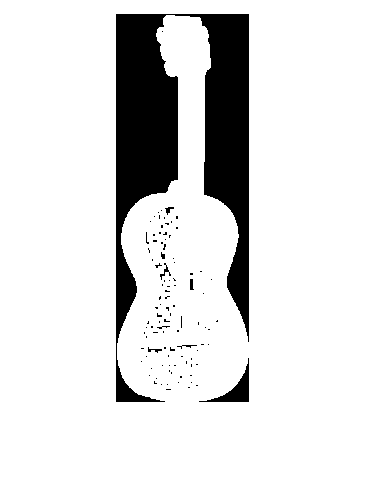

img = imread("../materials/guitar.tif");
[M, N] = size(img);
imshow(img, [])

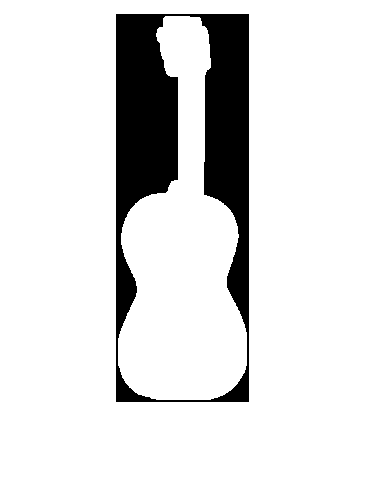

pad_img = padarray(img, [2,2], 0, "both");
result = zeros([M, N]);

for i=1:M
    for j=1:N
        flag = sum(pad_img(i:i+4,j:j+4),"all"); % use 5X5 with all ones as unit
        if flag ~= 0
            result(i, j) = 1;
        else
            result(i, j) = 0;
        end
    end
end

pad_img = padarray(result, [2, 2], 0, "both");

for i=1:M
    for j=1:N
        reflect = imrotate(pad_img(i:i+4,j:j+4), 180, "nearest");
        flag = bitand(reflect, pad_img(i:i+4,j:j+4)); % use 5X5 with all ones as unit
        flag = sum(flag,"all");
        if flag == 25
            result(i, j) = 1;
        else
            result(i, j) = 0;
        end
    end
end
imshow(result,[])